# Marginal cost data regression using polyfit function

## Load cleaned seasonal marginal cost data

load cleanedSel4QMCSeasons.mat
Seasons = ["Spring", "Summer", "Autumn", "Winter"];

## Show distribution of seasonal marginal cost data of 4 selected market participants

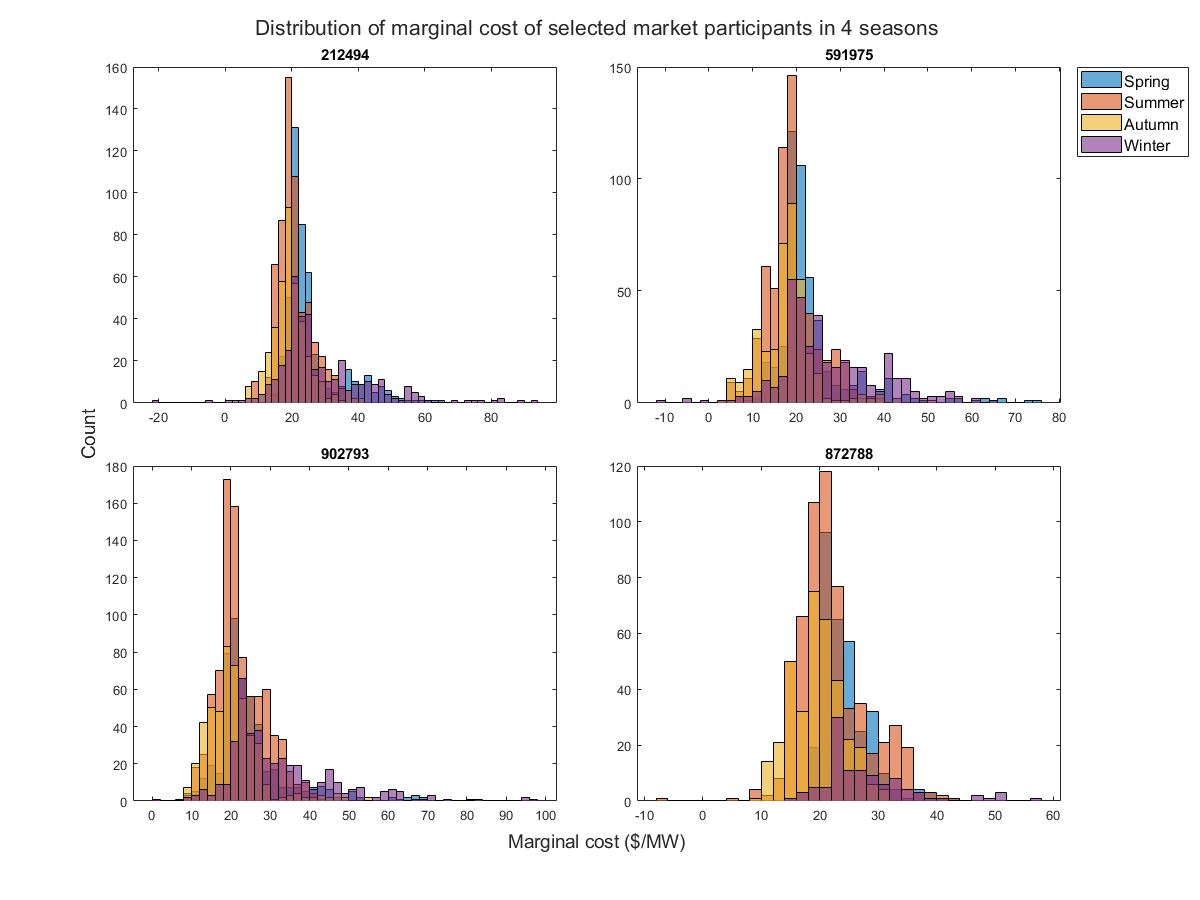

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
for n=1:4
    nexttile;
    partID = sel4PartIDs(n);
    hold on;
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        histogram(selQMCOneSeason.MCMarket, "BinWidth", 2);
    end
    hold off; box on;
    title(partID);
    if n==2
        legend(["Spring", "Summer", "Autumn", "Winter"], "Location","bestoutside", "FontSize", 12);
    end    
end
xlabel(t, "Marginal cost ($/MW)", "FontSize", 14);
ylabel(t, "Count", "FontSize", 14);
title(t, "Distribution of marginal cost of selected market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);

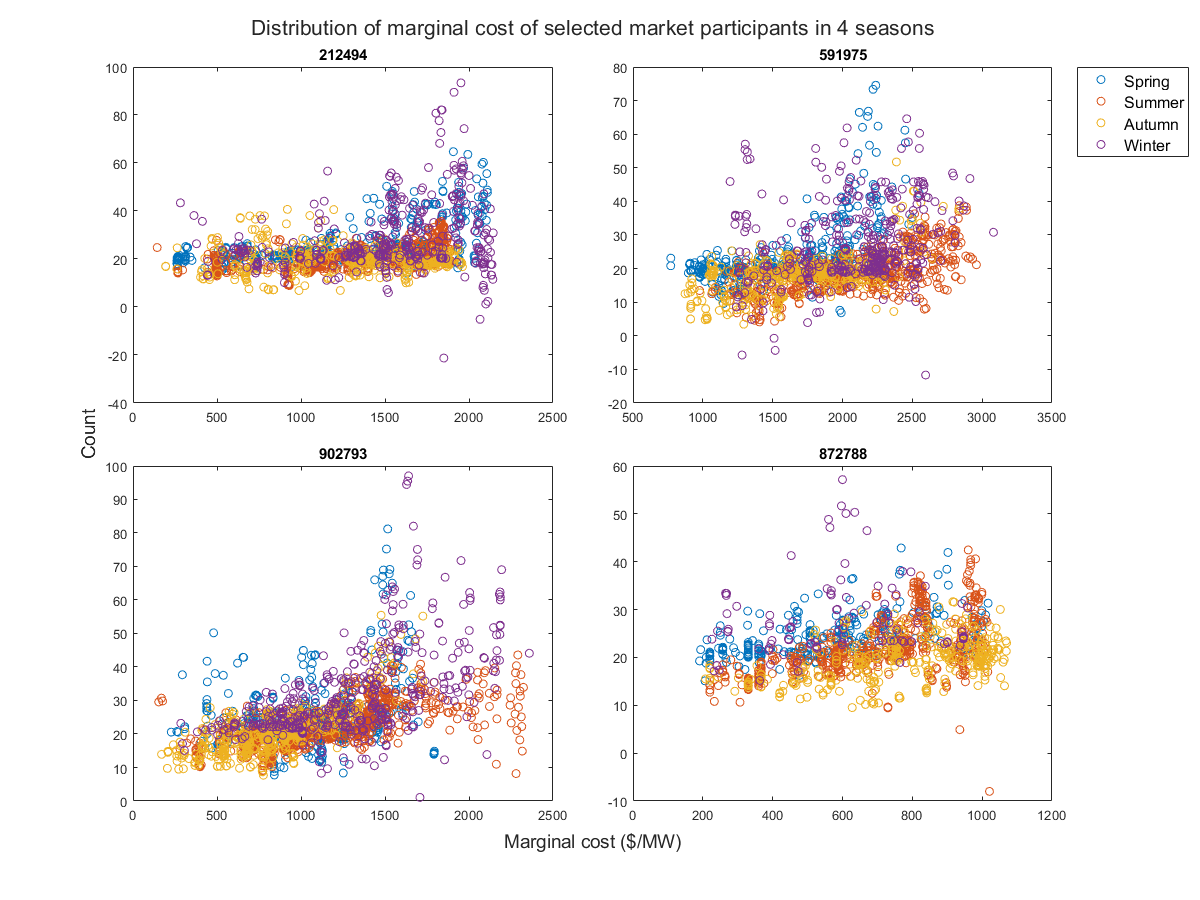

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
for n=1:4
    nexttile;
    partID = sel4PartIDs(n);
    hold on;
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        scatter(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 'o');
    end
    hold off; box on;
    title(partID);
    if n==2
        legend(["Spring", "Summer", "Autumn", "Winter"], "Location","bestoutside", "FontSize", 12);
    end    
end
xlabel(t, "Marginal cost ($/MW)", "FontSize", 14);
ylabel(t, "Count", "FontSize", 14);
title(t, "Distribution of marginal cost of selected market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);

## Fit quadratic relations of marginal cost and quantity

quadQMCSeason = zeros(4, 4, 3);
quadSSeason = cell(4, 4, 1);
quadMuSeason = zeros(4, 4, 2);
for n=1:4
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        [p, S, mu] = polyfit(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 2);
        [y_fit, delta] = polyval(p, selQMCOneSeason.Awarded, S, mu);
        sel4CleanedQMCSeason{n, s}.MCQuadFit = y_fit;
        sel4CleanedQMCSeason{n, s}.MCQuadDelta = delta;
        sel4CleanedQMCSeason{n, s}.MCQuadError = sel4CleanedQMCSeason{n, s}.MCMarket - sel4CleanedQMCSeason{n, s}.MCQuadFit;
        quadQMCSeason(n, s, :) = p;
        quadSSeason{n, s} = S;
        quadMuSeason(n, s, :) = mu.';
    end
    
end

## Fit cubic relations of marginal cost and quantity

cubicQMCSeason = zeros(4, 4, 4);
cubicSSeason = cell(4, 4, 1);
cubicMuSeason = zeros(4, 4, 2);
for n=1:4
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        [p, S, mu] = polyfit(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 3);
        [y_fit, delta] = polyval(p, selQMCOneSeason.Awarded, S, mu);
        sel4CleanedQMCSeason{n, s}.MCCubicFit = y_fit;
        sel4CleanedQMCSeason{n, s}.MCCubicDelta = delta;
        sel4CleanedQMCSeason{n, s}.MCCubicError = sel4CleanedQMCSeason{n, s}.MCMarket - sel4CleanedQMCSeason{n, s}.MCCubicFit;
        cubicQMCSeason(n, s, :) = p;
        cubicSSeason{n, s} = S;
        cubicMuSeason(n, s, :) = mu.';
    end    
end

## Visualize quadratic relation

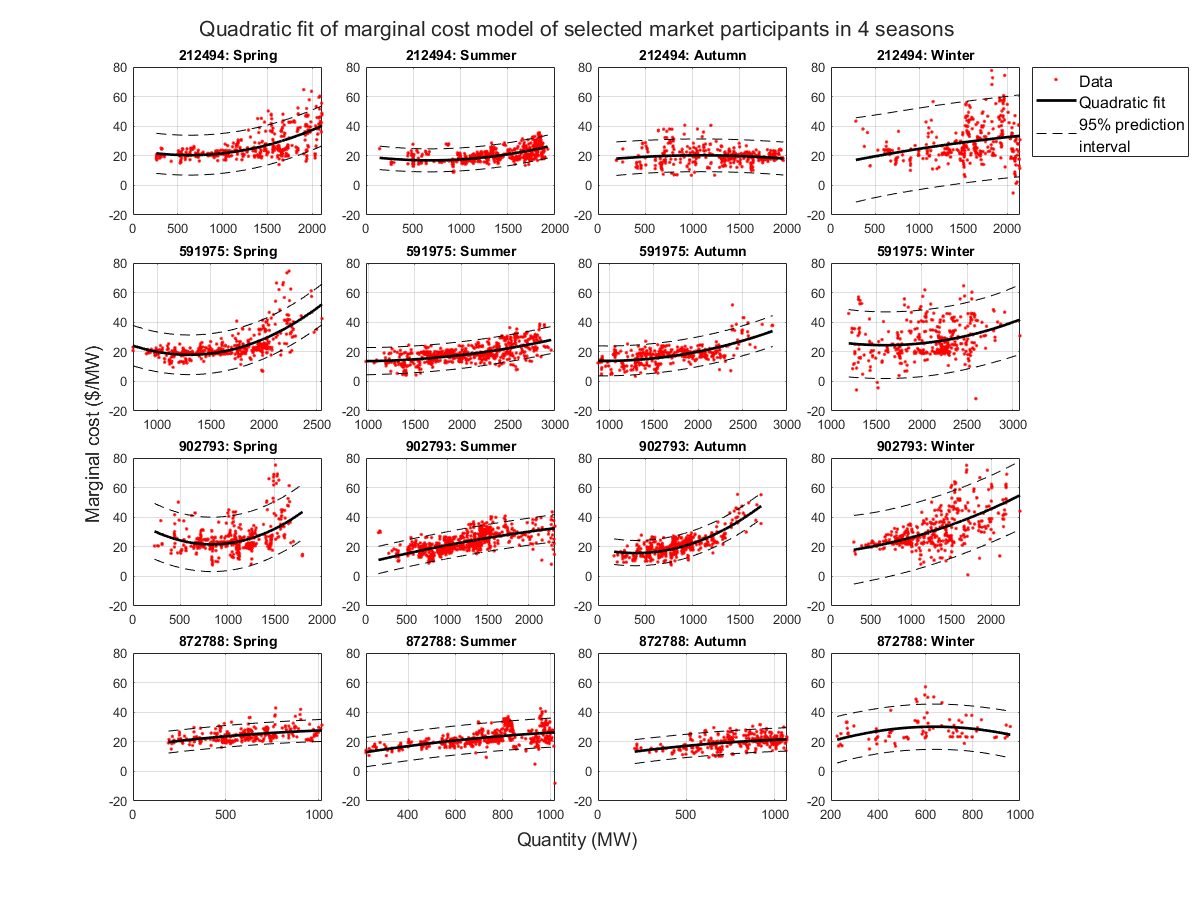

% Plot quantity vs marginal cost of selected market participants
figure;
t = tiledlayout(4, 4, "TileSpacing","compact");
for n=1:4
    for s=1:4
        nexttile;
        partID = sel4PartIDs(n);
        Season = Seasons(s);
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        % Plot cleaned data
        scatter(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 'r.');
        hold on;
        % Plot quadratic estimation
        plot(selQMCOneSeason.Awarded, selQMCOneSeason.MCQuadFit, 'k-', 'Linewidth', 2);
        quadUpper = selQMCOneSeason.MCQuadFit + 2*selQMCOneSeason.MCQuadDelta;
        quadLower = selQMCOneSeason.MCQuadFit - 2*selQMCOneSeason.MCQuadDelta;
        plot(selQMCOneSeason.Awarded, quadUpper, 'k--', selQMCOneSeason.Awarded, quadLower,'k--');
        title(partID + ": " + Season);
        ylim([-20, 80]);
        hold off; box on; grid on;
        if (n==1) && (s==4)
            legend(["Data", "Quadratic fit", "95% prediction\newlineinterval"], "Location","bestoutside", "FontSize", 12);
        end       
    end
end
xlabel(t, "Quantity (MW)", "FontSize", 14);
ylabel(t, "Marginal cost ($/MW)", "FontSize", 14);
title(t, "Quadratic fit of marginal cost model of selected market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/MCQuadFitSeason.png");

## Visualize cubic relation

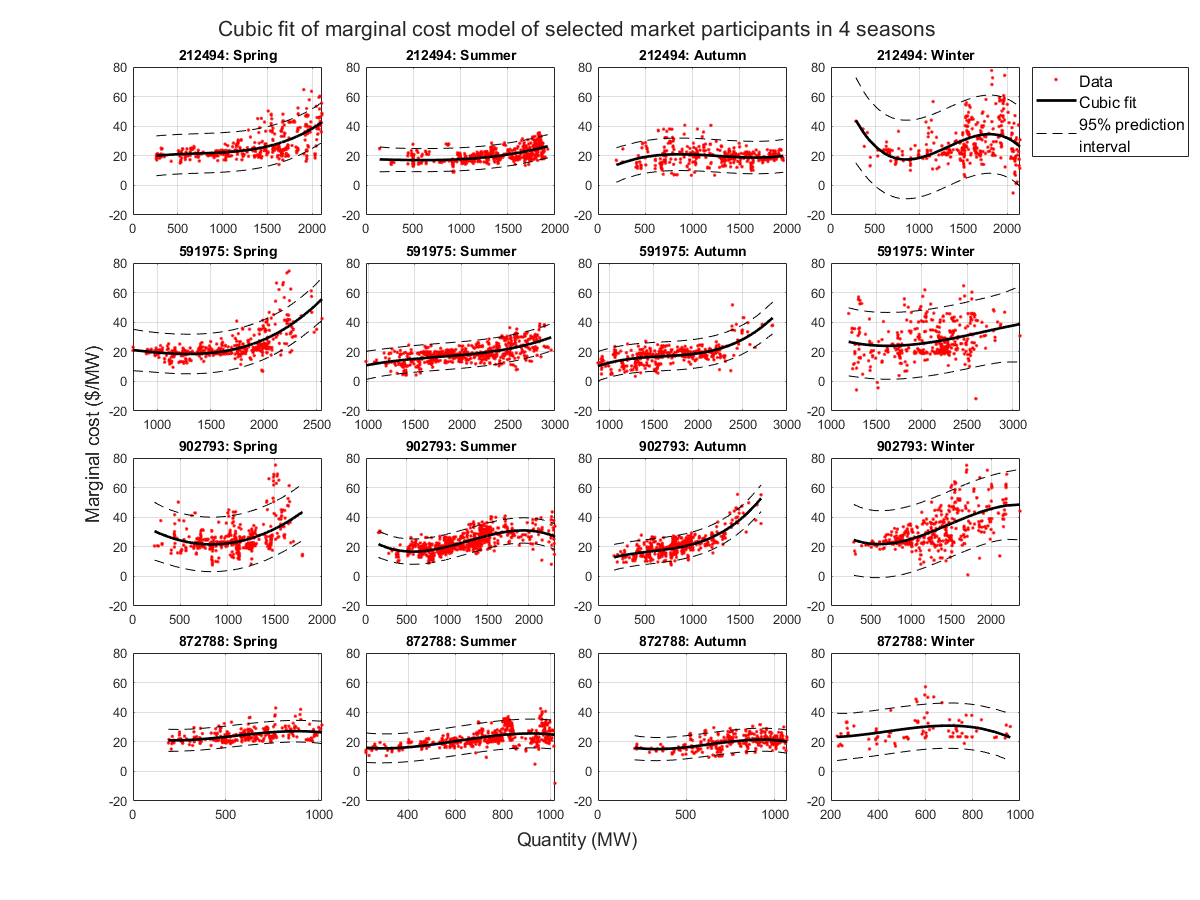

% Plot quantity vs marginal cost of selected market participants
figure;
t = tiledlayout(4, 4, "TileSpacing","compact");
for n=1:4
    for s=1:4
        nexttile;
        partID = sel4PartIDs(n);
        Season = Seasons(s);
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        % Plot cleaned data
        scatter(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 'r.');
        hold on;
        % Plot quadratic estimation
        plot(selQMCOneSeason.Awarded, selQMCOneSeason.MCCubicFit, 'k-', 'Linewidth', 2);
        quadUpper = selQMCOneSeason.MCCubicFit + 2*selQMCOneSeason.MCCubicDelta;
        quadLower = selQMCOneSeason.MCCubicFit - 2*selQMCOneSeason.MCCubicDelta;
        plot(selQMCOneSeason.Awarded, quadUpper, 'k--', selQMCOneSeason.Awarded, quadLower,'k--');
        title(partID + ": " + Season);
        ylim([-20, 80]);
        hold off; box on; grid on;
        if (n==1) && (s==4)
            legend(["Data", "Cubic fit", "95% prediction\newlineinterval"], "Location","bestoutside", "FontSize", 12);
        end       
    end
end
xlabel(t, "Quantity (MW)", "FontSize", 14);
ylabel(t, "Marginal cost ($/MW)", "FontSize", 14);
title(t, "Cubic fit of marginal cost model of selected market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/MCCubicFitSeason.png");

## Show fitness of the quadratic and cubic models

corrQuadSeason = zeros(4, 4, 1);
corrCubicSeason = zeros(4, 4, 1);
RMSEQuadSeason = zeros(4, 4, 1);
RMSECubicSeason = zeros(4, 4, 1);
for n=1:4
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        % Calculate correlation coefficient
        quadR= corrcoef(selQMCOneSeason.MCMarket, selQMCOneSeason.MCQuadFit);
        cubicR = corrcoef(selQMCOneSeason.MCMarket, selQMCOneSeason.MCCubicFit);
        corrQuadSeason(n, s)= quadR(1, 2);
        corrCubicSeason(n, s) = cubicR(1, 2);
        % Calculate RMSE
        RMSEQuadSeason(n, s) = sqrt(mean(selQMCOneSeason.MCQuadError.^2));
        RMSECubicSeason(n, s) = sqrt(mean(selQMCOneSeason.MCCubicError.^2));
    end  
end
sel4PartIDs = categorical(sel4PartIDs);

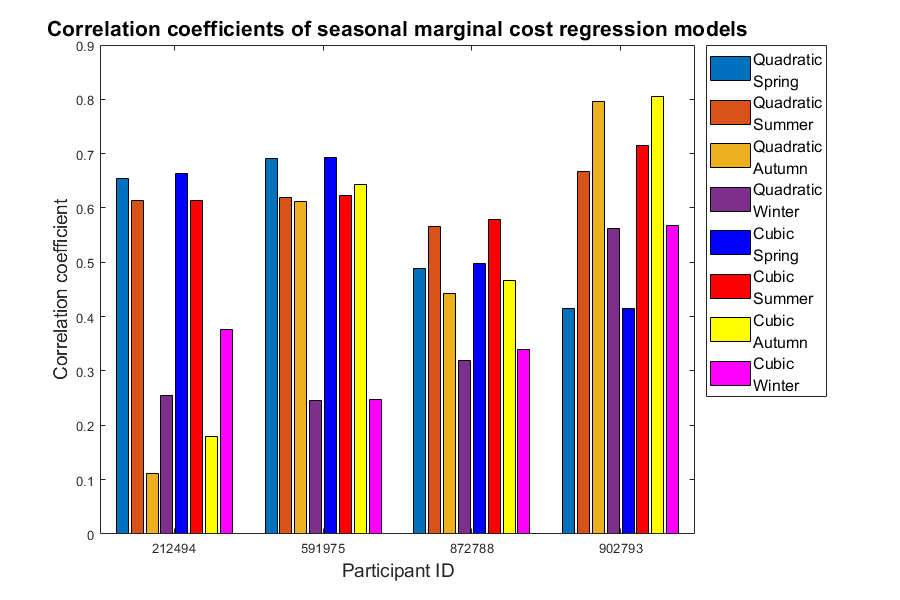

figure;
b = bar(sel4PartIDs, [corrQuadSeason, corrCubicSeason]);
b(5).FaceColor = 'b';
b(6).FaceColor = 'r';
b(7).FaceColor = 'y';
b(8).FaceColor = 'm';
legend(["Quadratic\newlineSpring","Quadratic\newlineSummer","Quadratic\newlineAutumn","Quadratic\newlineWinter", ...
    "Cubic\newlineSpring","Cubic\newlineSummer","Cubic\newlineAutumn","Cubic\newlineWinter"], "Location","bestoutside", "FontSize", 12);
xlabel("Participant ID", "FontSize", 14);
ylabel("Correlation coefficient", "FontSize", 14);
title("Correlation coefficients of seasonal marginal cost regression models", "FontSize", 16);
set(gcf, "Position", [50, 50, 900, 600]);
saveas(gcf, "../model_output/figures/corrCoefPolyfitSeason.png");

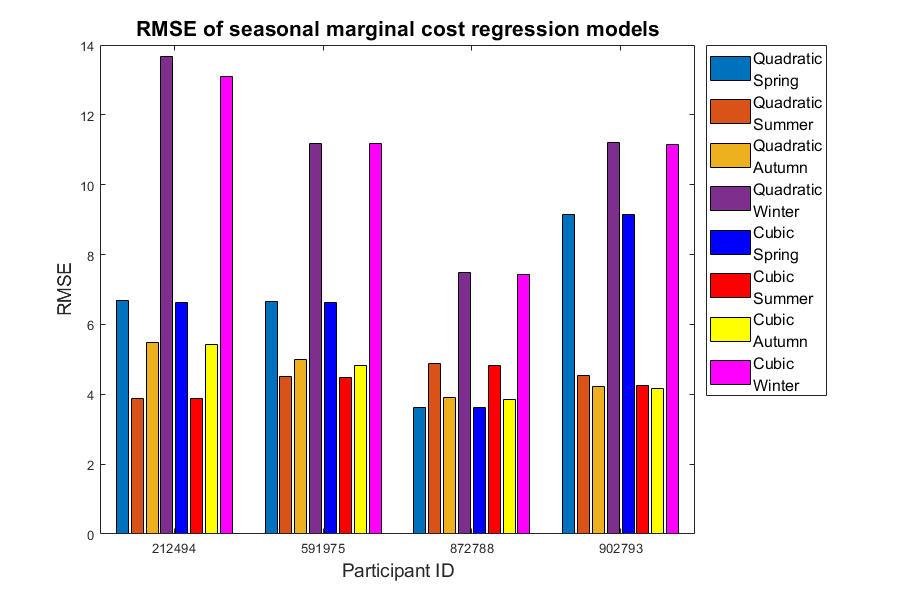

figure;
b = bar(sel4PartIDs, [RMSEQuadSeason, RMSECubicSeason]);
b(5).FaceColor = 'b';
b(6).FaceColor = 'r';
b(7).FaceColor = 'y';
b(8).FaceColor = 'm';
legend(["Quadratic\newlineSpring","Quadratic\newlineSummer","Quadratic\newlineAutumn","Quadratic\newlineWinter", ...
    "Cubic\newlineSpring","Cubic\newlineSummer","Cubic\newlineAutumn","Cubic\newlineWinter"], "Location","bestoutside", "FontSize", 12);
xlabel("Participant ID", "FontSize", 14);
ylabel("RMSE", "FontSize", 14);
title("RMSE of seasonal marginal cost regression models", "FontSize", 16);
set(gcf, "Position", [50, 50, 900, 600]);
saveas(gcf, "../model_output/figures/RMSEPolyfitSeason.png");

## Write fitted models to file

sel4PolyFitQMCSeason = sel4CleanedQMCSeason;
save("MCQuadFitSeason.mat", "quadQMCSeason", "quadSSeason", "quadMuSeason", "-mat");
save("MCCubicFitSeason.mat", "cubicQMCSeason", "cubicSSeason", "cubicMuSeason", "-mat");
save("MCSeasonFitResults.mat", "sel4PolyFitQMCSeason", "sel4PartIdx", "sel4PartIDs", "-mat");